job_dir = "./output/jobs/allrisk_base_trunc_60_dist/";
params = yaml.loadFile(fullfile(job_dir, "job_config.yaml"));
base_simulation_table = load(fullfile(job_dir, "raw", "base_simulation_table.mat"));
base_simulation_table = base_simulation_table.base_simulation_table;

event_sim_table = base_simulation_table(~isnan(base_simulation_table.yr_start), :);

% Basic simulation parameters
sim_num = event_sim_table.sim_num;
num_sims = params.num_simulations;
num_events = height(event_sim_table);
max_years = params.sim_periods;

% Event timing information
year_start = event_sim_table.yr_start;
year_dur = event_sim_table.actual_dur;
month_start = (year_start - 1) * 12 + 1;
month_dur = ceil(year_dur * 12);
max_month_dur = max(month_dur);

is_false = event_sim_table.is_false;
surveil_thresholds = cell2mat(params.surveillance_thresholds);
prep_start_month = run_surveillance(...
    event_sim_table.posterior1, ...
    event_sim_table.posterior2, ...
    is_false, ...
    false, ... % Enhanced surveillance
    surveil_thresholds ...
 );
false_pos_detected = isnan(prep_start_month) & is_false;

[z_m, z_o] = get_adv_capacity(params);
params.z_m = z_m;
params.z_o = z_o;

% Array denoting which matrix elements correspond to active pandemics
active_idx = (month_dur >= (1:max_month_dur)) .* ~is_false; % E x M

% Discount and growth factors
pv_factors_annual = (1+params.r).^(-(1:max_years));
months_matrix = repmat(1:max_month_dur, num_events, 1); % E x M
growth_factors_monthly = (1 + params.y).^((month_start + months_matrix - 1)/12);
pv_factors_monthly = (1/(1 + params.r)).^((month_start + months_matrix - 1)/12);

event_start_idx = sub2ind([num_sims, max_years], sim_nums, year_start);
[sim_idx, year_idx] = get_event_list_to_sim_year_idx(sim_nums, month_start, month_dur);

build_years = params.adv_cap_build_period;
non_build_years = max_years - build_years;

build_rate_m = params.z_m / build_years;
build_rate_o = params.z_o / build_years;

% Calculate advance and surge capacity
base_cap_m = params.x_avail * params.mRNA_share;
base_cap_o = params.x_avail * (1 - params.mRNA_share);
[max_cap_m, max_cap_o] = get_target_capacity(params);
frac_retained = params.capacity_kept;

% Advance capacity over time
adv_cap_m = [build_rate_m * (1:build_years), repmat(params.z_m, 1, non_build_years)]; % 1 x Y
adv_cap_o = [build_rate_o * (1:build_years), repmat(params.z_o, 1, non_build_years)]; % 1 x Y

delta_cap = base_cap_m;
surge_retained = params.capacity_kept;

year_end = min(year_start + year_dur, max_years); % Month where capacity should be reduced
cap_event_start_idx = sub2ind([num_sims, max_years], sim_nums(~false_pos_detected), year_start(~false_pos_detected));
cap_event_end_idx = sub2ind([num_sims, max_years], sim_nums(~false_pos_detected), year_end(~false_pos_detected));

surge_cap_m = zeros(num_sims, max_years);
surge_cap_m(cap_event_start_idx) = delta_cap;
surge_cap_m(cap_event_end_idx) = -(1 - surge_retained) * delta_cap;

surge_cap_m = cumsum(surge_cap_m, 2);
all_cap_m = surge_cap_m + base_cap_m + adv_cap_m;
exceed_idx = all_cap_m > max_cap_m;

new_surge_cap = zeros(size(surge_cap_m));
new_surge_cap(exceed_idx) = surge_cap_m(exceed_idx) - (all_cap_m(exceed_idx) - max_cap_m); % Enforce ceiling
new_surge_cap(new_surge_cap < 0) = 0;

year_end = min(year_start + year_dur, max_years); % Month where capacity should be reduced
cap_event_start_idx = sub2ind([num_sims, max_years], sim_nums(~false_pos_detected), year_start(~false_pos_detected));
cap_event_end_idx = sub2ind([num_sims, max_years], sim_nums(~false_pos_detected), year_end(~false_pos_detected));

surge_cap_m = zeros(num_sims, max_years);
surge_cap_m(cap_event_start_idx) = delta_cap;
surge_cap_m(cap_event_end_idx) = -(1 - surge_retained) * delta_cap;

surge_cap_m = cumsum(surge_cap_m, 2);
all_cap_m = surge_cap_m + base_cap_m + adv_cap_m;
exceed_idx = all_cap_m > max_cap_m;
surge_cap_m(exceed_idx) = surge_cap_m(exceed_idx) - (all_cap_m(exceed_idx) - max_cap_m); % Enforce ceiling
surge_cap_m(surge_cap_m < 0) = 0;

event_surge_cap = surge_cap_m(cap_event_start_idx);

% Get the existing surge capacity right before each event
pre_event_surge_cap = zeros(size(event_surge_cap));
valid_idx = year_start > 1 & ~false_pos_detected;
pre_event_idx = sub2ind([num_sims, max_years], sim_nums(valid_idx), year_start(valid_idx) - 1); 
pre_event_surge_cap(valid_idx) = surge_cap_m(pre_event_idx);

% Calculate the incremental surge capacity needed
event_surge_cap_diff = event_surge_cap - pre_event_surge_cap;
event_surge_cap_diff(event_surge_cap_diff < 0) = 0;

% Calculate capital costs for the incremental capacity
event_surge_cap_cost = capital_costs(event_surge_cap_diff, params, 0, 1, 0);

% Place costs in the output matrix at event start times
surge_cap_cost = zeros(num_sims, max_years);
surge_cap_cost(cap_event_start_idx) = event_surge_cap_cost;

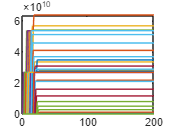

cum_surge_cap_cost = cumsum(surge_cap_cost, 2);
plot(1:200, cum_surge_cap_cost(1:2000, :));

% Now let's try just using the function
[surge_cap_m, surge_cap_m_cost] = ...
    get_event_capacity(sim_nums, year_start, false_pos_detected, year_dur, max_years, base_cap_m, frac_retained, base_cap_m, adv_cap_m, max_cap_m, params, 1, num_sims);
[surge_cap_o, surge_cap_o_cost] = ...
    get_event_capacity(sim_nums, year_start, false_pos_detected, year_dur, max_years, base_cap_o, frac_retained, base_cap_o, adv_cap_o, max_cap_o, params, 0, num_sims);

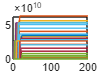

cum_surge_cap_m_cost = cumsum(surge_cap_m_cost, 2);
plot(1:200, cum_surge_cap_m_cost(1:2000, :));

% Calculate rental income
surge_cap_m_annual_value = surge_cap_m .* params.k_m;
surge_cap_o_annual_value = surge_cap_o .* params.k_o;
surge_cap_annual_cap_cost = surge_cap_m_cost + surge_cap_o_cost;
surge_cap_annual_value = surge_cap_m_annual_value + surge_cap_o_annual_value;

% Calculate rental income
rentable_cap = (adv_cap_m + surge_cap_m) + (adv_cap_o + surge_cap_o);
rental_income_fractions = get_rental_fractions(rentable_cap, params.theta .* (base_cap_m + base_cap_o));

surge_cap_maintenance_costs = get_capacity_maintenance_cost(surge_cap_annual_value, params);
surge_cap_maintenance_costs_rent_adjusted = surge_cap_maintenance_costs .* (1 - rental_income_fractions);
surge_cap_total_costs_nom = surge_cap_annual_cap_cost + surge_cap_maintenance_costs_rent_adjusted;
surge_cap_total_costs_pv = surge_cap_total_costs_nom .* pv_factors_annual;

temp = surge_cap_total_costs_nom(any(surge_cap_total_costs_nom(30:200) > 0, 2), :);

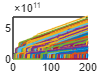

outmat = readmatrix(fullfile(job_dir, "raw", "advance_capacity_ts_inp_cap_n.csv"));
cum_outmat = cumsum(outmat, 2);
plot(1:200, cum_outmat(1:2000,:))

baseline_surge_cap_cost = readmatrix(fullfile(job_dir, "raw", "baseline_ts_inp_cap_n.csv"));
advance_cap_surge_cap_cost = readmatrix(fullfile(job_dir, "raw", "advance_capacity_ts_inp_cap_n.csv"));

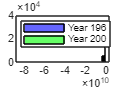

difference = advance_cap_surge_cap_cost - baseline_surge_cap_cost;

figure('Position', [100, 100, 800, 600]);

histogram(difference(:, 196), 'FaceColor', 'blue', 'DisplayName', 'Year 196');
hold on;
histogram(difference(:,200), 'FaceColor', 'green', 'DisplayName', 'Year 200');
legend('Location', 'northwest')
hold off;

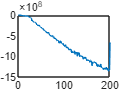

plot(mean(difference, 1));

function [sim_idx, year_idx] = get_event_list_to_sim_year_idx(sim_nums, month_start, month_dur)
    % Create indices for converting event x month matrix to simulation x year matrix
    %
    % Args:
    %   values_matrix: Matrix of values with dimensions (events x months)
    %   event_months: Starting month for each event (1-based)
    %   sim_nums: Array of simulation numbers for each event
    %   month_dur: Duration in months for each event
    %
    % Returns:
    %   sim_idx: Array of simulation indices for accumarray
    %   year_idx: Array of year indices for accumarray
    %   values_flat: Flattened values from the input matrix
    
    % Get simulation indices by repeating each sim number by its duration
    sim_idx = repelem(sim_nums, month_dur);
    
    % Get month indices by expanding each event's start month
    month_idx = cell2mat(arrayfun(@(s,d) (s:(s+d-1))', ...
                         month_start, month_dur, ...
                         'UniformOutput',false));
                         
    % Convert to year indices
    year_idx = floor((month_idx-1)./12) + 1;

end


function sim_year_matrix = event_list_to_sim_year(values_matrix, sim_idx, year_idx, num_sims, max_years, active_idx)
    % Convert event x month matrix to simulation x year matrix
    %
    % Args:
    %   values_matrix: Matrix of values with dimensions (events x months)
    %   event_months: Starting month for each event (1-based)
    %   sim_nums: Array of simulation numbers for each event
    %   month_dur: Duration in months for each event
    %   num_sims: Number of simulations
    %   max_years: Maximum number of years
    %
    % Returns:
    %   sim_year_matrix: Matrix of values with dimensions (num_sims x max_years)
    values_max_t = values_matrix';
    values = values_max_t((active_idx == 1)');

    sim_year_matrix = accumarray([sim_idx, year_idx], ...
                                 values, ...
                                 [num_sims, max_years], ...
                                 @sum, ...
                                 0);
end


function prep_start_month_arr = run_surveillance(posterior1, posterior2, is_false_arr, enhanced_surveillance, threshold_surveil_arr)
	% only computes, no random number generation

	% Extract thresholds
	threshold_no_surveil = threshold_surveil_arr(1);
	threshold_surveil = threshold_surveil_arr(2);

	% Compute true state and prepare decisions
	prepare_decision1 = posterior1 > (enhanced_surveillance * threshold_surveil + ~enhanced_surveillance * threshold_no_surveil);
	prepare_decision2 = posterior2 > threshold_surveil;

	% Initialize prep_start_month_arr with default value
	prep_start_month_arr = 2 * ones(size(is_false_arr));

	if enhanced_surveillance
		% Enhanced surveillance logic
		prep_start_month_arr(prepare_decision1) = 0;
		prep_start_month_arr(~prepare_decision1 & prepare_decision2) = 1;
	else
		% No enhanced surveillance logic
		prep_start_month_arr(prepare_decision1) = 1; % We use prep decision 1 as we don't get better signal.
	end

	% Handle cases where no pandemic was correctly anticipated
	no_pandemic_correctly_anticipated = is_false_arr & ((~enhanced_surveillance & ~prepare_decision1) | (enhanced_surveillance & ~prepare_decision1 & ~prepare_decision2));
	prep_start_month_arr(no_pandemic_correctly_anticipated) = NaN;

	% Ensure prep_start_month_arr is a column vector
	prep_start_month_arr = prep_start_month_arr(:);
end